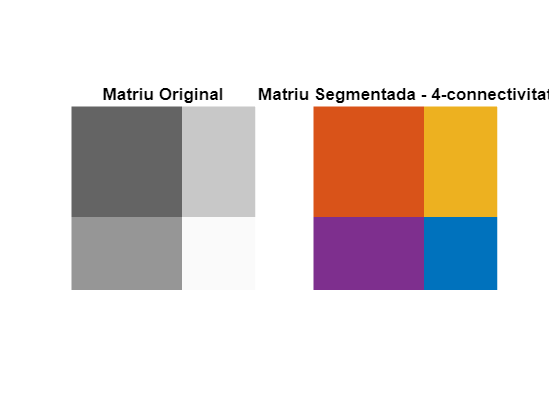

% PRACTICA 2: Segmentació d’una matriu en tons de grisos mitjançant creixement de regió

% Iniciem un comptador de temps per mesurar el temps total de segmentació
tic

% Definim manualment la matriu d'entrada en escala de grisos (valors entre 0 i 255)
matriu_1 = [100 100 100 200 200;
            100 100 100 200 200;
            100 100 100 200 200;
            150 150 150 250 250;
            150 150 150 250 250];

% Convertim la matriu a tipus double per poder fer càlculs amb decimals.
% No normalitza entre 0 i 1, només permet operacions com divisions i mitjanes amb precisió.
matriu = double(matriu_1);

% Inicialitzem la matriu de resultat amb zeros
Resultat = zeros(size(matriu));

% Inicialitzem valors
etiqueta = 1;
th = 20;  % Llindar de tolerància

% Definim la connectivitat (4 o 8)
Conectivitat = 4;  % ← Canvia-ho lliurement

% Utilitzem una cua estàtica (prealocada) per evitar redimensionaments constants i millorar rendiment
mida_cua = numel(matriu);
vector_x = zeros(mida_cua, 1);
vector_y = zeros(mida_cua, 1);

% Busquem el primer píxel no etiquetat
[x, y] = find(Resultat == 0, 1);

% Bucle principal: segmentem mentre quedin píxels per etiquetar
while ~isempty(x)
    mitjana = matriu(x, y);
    comptador = 1;
    Resultat(x, y) = etiqueta;

    % Inicialitzem la cua
    inici = 1;
    final = 1;
    vector_x(final) = x;
    vector_y(final) = y;

    % Definim els offsets segons la connectivitat triada
    if Conectivitat == 4
        offsets = [ -1,  0;   % Esquerra
                     0,  1;   % Dalt
                     1,  0;   % Dreta
                     0, -1];  % Baix
    elseif Conectivitat == 8
        offsets = [ -1,  0;    % Esquerra
                   -1,  1;    % Diagonal superior esquerra
                    0,  1;    % Dalt
                    1,  1;    % Diagonal superior dreta
                    1,  0;    % Dreta
                    1, -1;    % Diagonal inferior dreta
                    0, -1;    % Baix
                   -1, -1];   % Diagonal inferior esquerra
    else
        error('El valor de Conectivitat ha de ser 4 o 8.');
    end

    % Inici del creixement de regió
    while (inici <= final)
        % 'inici' indica el pròxim píxel a processar
        % 'final' indica on afegim nous píxels a la cua
        x1 = vector_x(inici);
        y1 = vector_y(inici);
        inici = inici + 1;

        for i = 1:size(offsets, 1)
            pixel_x = x1 + offsets(i, 1);
            pixel_y = y1 + offsets(i, 2);

            % Comprovem que estiguem dins dels límits
            if (pixel_x > 0 && pixel_x <= size(matriu, 1) && pixel_y > 0 && pixel_y <= size(matriu, 2))
                if (Resultat(pixel_x, pixel_y) == 0)
                    % Si la diferència amb la mitjana és dins del llindar
                    if abs(matriu(pixel_x, pixel_y) - mitjana) <= th
                        Resultat(pixel_x, pixel_y) = etiqueta;

                        final = final + 1;
                        vector_x(final) = pixel_x;
                        vector_y(final) = pixel_y;

                        comptador = comptador + 1;
                        mitjana = (mitjana * (comptador - 1) + matriu(pixel_x, pixel_y)) / comptador;
                    end
                end
            end
        end
    end

    % Busquem la següent zona no etiquetada
    [x, y] = find(Resultat == 0, 1);
    etiqueta = etiqueta + 1;
end

% Convertim les etiquetes en colors per visualitzar les regions
matriu_final = label2rgb(Resultat, lines(max(Resultat(:))), 'b', 'shuffle');

% Mostrem les imatges
figure;
subplot(1, 2, 1), imshow(uint8(matriu)), title('Matriu Original');
subplot(1, 2, 2), imshow(matriu_final), title(['Matriu Segmentada - ', num2str(Conectivitat), '-connectivitat']);


% Mostrem el temps total de segmentació
toc

Elapsed time is 0.145717 seconds.
